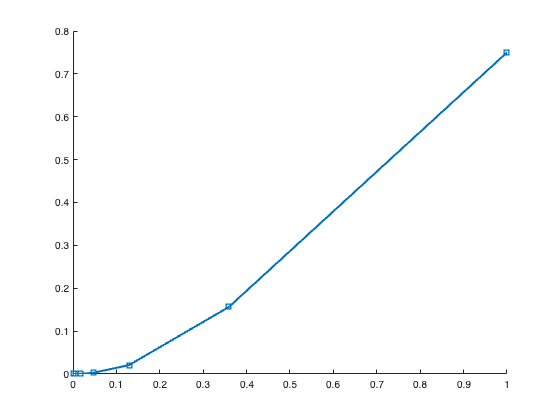

% Compare multiple (b,g,m)-BGM codes with [[4,2,2]]-code against local amplitude damping

% User-supplied BGM parameter list [b g m] rows:
bgm_list = [ ...
    2 2 1;  % (2,2,1)-BGM
      % (3,3,1)-BGM
    % add more rows as needed, e.g., 4 1 2
];

p_list = logspace(-4, 0, 10);
num_p  = numel(p_list);
noise  = "localampdamp";

% Baseline [[4,2,2]] code (full Hilbert, N=4)
[log0, log1] = codewords.four_qubit();
N_four = 4;

fid_four = zeros(num_p, 1);
for ii = 1:num_p
    p = p_list(ii);
    model_four = noisemodel(noise, p,N_four );    % pass number of qubits
    [fid_four(ii), ~] = optimisation(log0, log1, model_four);
end
infid_four = abs(1 - fid_four);

% Plot setup
figure; hold on;
loglog(p_list, infid_four, 's-', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', '[[4,2,2]]-Code');


% Loop over BGM configurations
for row = 1:size(bgm_list, 1)
    b = bgm_list(row, 1);
    g = bgm_list(row, 2);
    m = bgm_list(row, 3);

    fullHilbert = true;  % use full 2^N space to match optimisation/noise
    useSparse   = true;  % keep memory manageable

    % Build BGM codewords
    [l0, l1] = codewords.bgmcode(b, g, m, fullHilbert, useSparse);

    % Number of physical qubits
    N_bgm = 2*b*m + g;

    % Fidelity sweep
    fid_bgm = zeros(num_p, 1);
    for ii = 1:num_p
        p = p_list(ii);
        model_bgm = noisemodel(noise, p, length(l0));  % pass N, not length(l0)
        [fid_bgm(ii), ~] = optimisation(l0, l1, model_bgm);
    end

    infid_bgm = abs(1 - fid_bgm);
    label = sprintf('(%d,%d,%d)-BGM', b, g, m);
    loglog(p_list, infid_bgm, 'o-', 'LineWidth', 2, 'MarkerSize', 6, 'DisplayName', label);
end

Error using cell
Requested array exceeds the maximum possible variable size.

Error in noisemodel/local_ampdamp (line 182)
        Kraus = cell(1, numK);

Error in noisemodel (line 20)
            model = local_ampdamp(param, dim);      

Related d


xlabel('Error Probability (p)', 'FontSize', 12);
ylabel('|1 - F|', 'FontSize', 12);
title('Local amplitude damping', 'FontSize', 14);
legend('FontSize', 11, 'Location', 'best');
grid on; hold off;